# Anomaly Detection

An anomaly detection algorithm will be implemented to detect anomalous behavior in server computers. We will then apply this anomaly detection algorithm to a more realsitic dataset (where each example is described by 11 features instead of 2). 

This anomaly detection algorithm is adapted from the first part of the eighth exercise from Andrew Ng’s Machine Learning Course on Coursera.

The anomaly detection algorithm will be implemented to detect anomalous behavior in server computers. The features measure the throughput (mb/s) and latency (ms) of response of each server. A sample dataset is provided, with m = 307 examples of how servers were behaving. Thus, we have an unlabeled dataset. It is suspected that the vast majority of these examples are “normal” (non-anomalous) examples of the servers operating normally, but there might also be some examples of servers acting anomalously within this dataset.

We will use a Gaussian model to detect anomalous examples in the dataset. First, we will start with a 2D dataset; which will allow to visualize what the algorithm is doing. On that dataset, a Gaussian distribution will be fitted in order to find values that have very low probability and hence can be considered anomalies. After that, the anomaly detection algorithm will be applied to a larger dataset with many dimensions.

Let's start with the 2D example. 

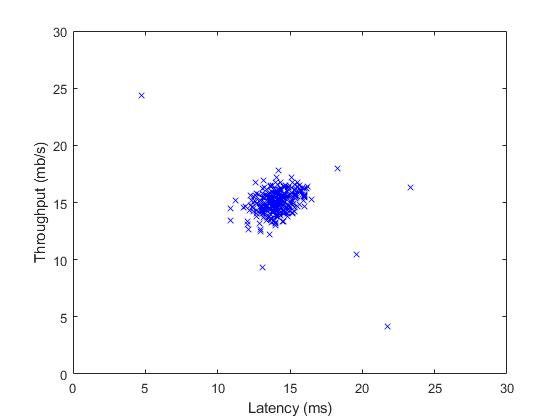

% Load and visualize the example dataset
load('ex8data1.mat');
plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

To perform anomaly detection, first a model will be fitted to the data’s distribution. Given a training set $\{x^{(1)},\dots,x^{(m)}\}$ (where $x^{(i)}\in\mathbb{R}^n$), we will estimate the Gaussian distribution for each of the features $x_i$. For each feature $i = 1\ldots n$ we will find parameters $\mu_i$ and $\sigma^2_i$ that fit the data in the $i$-th dimension $\{x_i^{(1)},\ldots,x^{(m)}_i\}$(the $i$-th dimension of each example).

    The Gaussian distribution is given by


$$p(x;\mu,\sigma^2)=\frac{1}{\sqrt{2\pi\sigma^2}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$$


where $\mu$ is the mean and $\sigma^2$ controls the variance. To estimate the mean, we will use:

$\mu_i = \frac{1}{m}\sum_{j=1}^m{x^{(j)}}$,

and for the variance we will use:

$\sigma^2_i = \frac{1}{m}\sum_{j=1}^m{(x^{(j)}-\mu_j)^2}$.

The function estimateGaussian.m takes as input the data matrix `X` and should output an $n$-dimension vector `mu` that holds the mean of all the $n$ features and another $n$-dimension vector `sigma2` that holds the variances of all the features. We use a vectorized implementation for efficiency. 

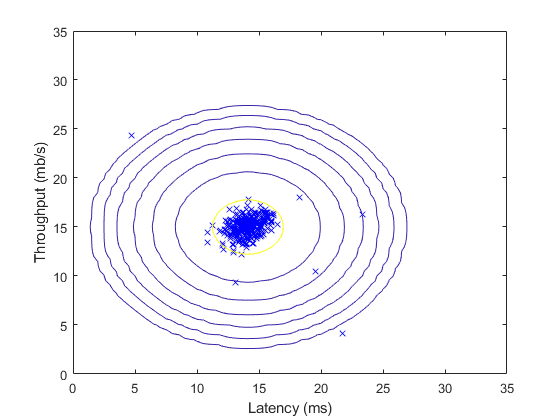

%  Estimate mu and sigma2
[mu, sigma2] = estimateGaussian(X);

%  Returns the density of the multivariate normal at each data point (row) of X
p = multivariateGaussian(X, mu, sigma2);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

The contours of the fitted Gaussian distribution are visualized above. From the plot, it can be seen that most of the examples are in the region with the highest probability, while the anomalous examples are in the regions with lower probabilities.

Now that the Gaussian parameters have been estimated, it can be investigated which examples have a very high probability given this distribution and which examples have a very low probability. The low probability examples are more likely to be the anomalies in the dataset. One way to determine which examples are anomalies is to select a threshold based on a cross validation set. An algorithm will be implemented to select the threshold $\epsilon$ using the $F_1$ score on a cross validation set.

The code in selectThreshold.m uses a cross validation set, where the label y=1 corresponds to an anomalous example, and the label y=0 corresponds to a normal example. 

The function `selectThreshold.m` should return two values; the first is the selected threshold $\epsilon$. If an example $x$ has a low probability $p(x) < \epsilon$, then it is considered to be an anomaly. The function should also return the $F_1$ score, which tells you how well you're doing on finding the ground truth anomalies given a certain threshold.  For many different values of ε, the resulting F1 score will be computed by computing how many examples the current threshold classifies correctly and incorrectly.

  The $F_1$ score is computed using precision (*prec*) and recall (*rec*):

$F_1 = \frac{2 ( prec)(rec)}{prec + rec}$,

You compute precision and recall by:


$$prec = \frac{tp}{tp + fp}$$



$$rec = \frac{tp}{tp + fn}$$


where

- $tp$ is the number of true positives: the ground truth label says it's an anomaly and our algorithm correctly classified it as an anomaly.

- $fp$ is the number of false positives: the ground truth label says it's not an anomaly, but our algorithm incorrectly classified it as an anomaly.

- $fn$ is the number of false negatives: the ground truth label says it's an anomaly, but our algorithm incorrectly classified it as not being anomalous.

In the code `selectThreshold.m`, a loop will try many different values of  $\epsilon$ and select the "best" based $\epsilon$ on the $F_1$ score. 

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 8.990853e-05


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.875000


Now, we can find the outliers in our training set!

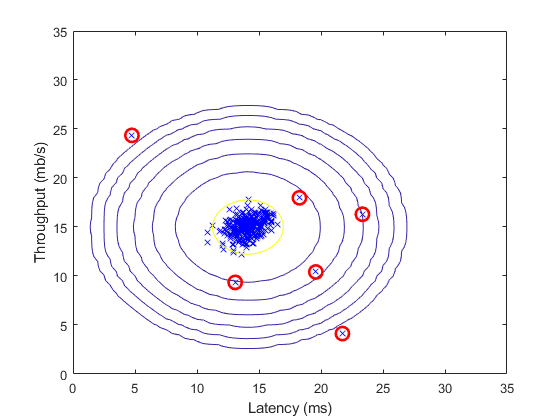


%  Find the outliers in the training set and plot the
outliers = find(p < epsilon);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');
%  Draw a red circle around those outliers
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

Clearly we have identified our outliers! 

The anomaly detection algorithm will be applied now on a more realistic and much harder dataset. In this dataset, each example is described by 11 features, capturing many more properties of the compute servers.

The code below will use your code to estimate the Gaussian parameters ($\mu_i$ and $\sigma^2_i$), evaluate the probabilities for both the training data `X` from which you estimated the Gaussian parameters, and do so for the the cross-validation set `Xval`. Finally, it will use `selectThreshold` to find the best threshold $\epsilon$. You should see a value `epsilon` of about `1.38e-18`, and 117 anomalies found.

%  Loads the second dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data2.mat');

%  Apply the same steps to the larger dataset
[mu, sigma2] = estimateGaussian(X);

%  Training set 
p = multivariateGaussian(X, mu, sigma2);

%  Cross-validation set
pval = multivariateGaussian(Xval, mu, sigma2);

%  Find the best threshold
[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 1.377229e-18


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.615385


fprintf('# Outliers found: %d\n', sum(p < epsilon));

# Outliers found: 117


Note that this anomaly detection system does not depend at all on the examples we've chosen! Thus, you can simply replace the imported data with data of your choosing, and detect anomalies in your own data! 